# **Calcium data analysis with electrophysiology**

    May 2018

    This script was originally a function. It itself calls on previously written functions such as *fire_detection*, which detects the location of fires within the electrophysiology recording or *fluorescence_variations*, which should be used to extract periods of Fluorescence_ON in the calcium data.

##         Opening the electrophysiology file

** abfload
opening 2018_04_05_mXXX_AK15__0503.abf..
data were acquired in waveform fixed-length mode


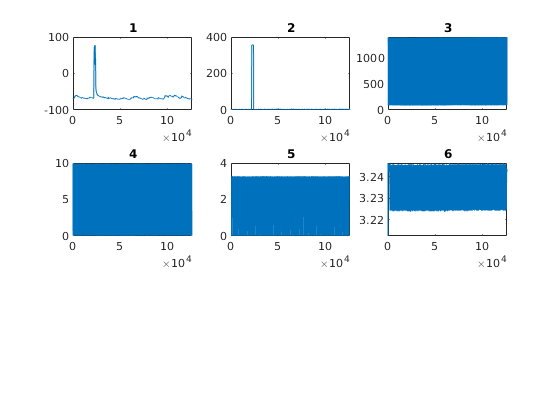

[electrophysiology_data,si,h] = opening_abf('*0503.abf');

ephys_sweeps = h.lActualEpisodes

ephys_sweeps = 30

channel = 1 %the channel to align data on, id est the spike train

channel = 1

##        Opening the calcium file and defining the ROIs with *zprofile*

calcium_file = '2018-03-05_turtle_AK15_m0503__c7_hilolikefiltered.tiff'

calcium_file = '2018-03-05_turtle_AK15_m0503__c7_hilolikefiltered.tiff'

Discarding last ROI. Select a new one.
Discarding last ROI. Select a new one.
Discarding last ROI. Select a new one.


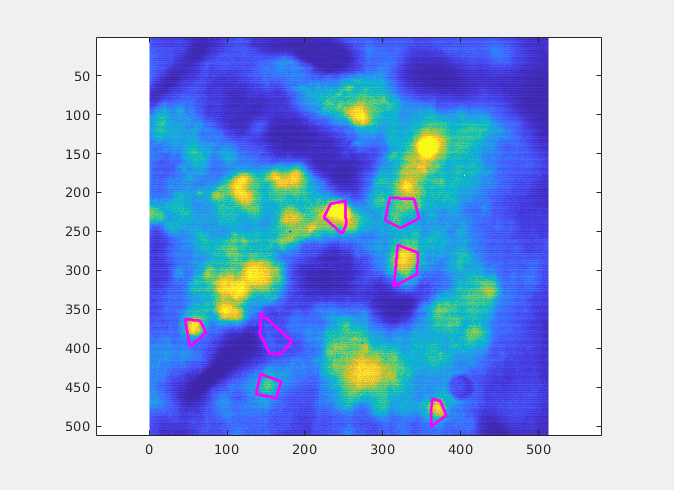

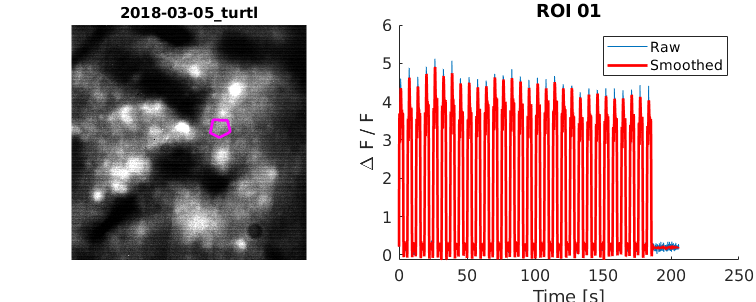

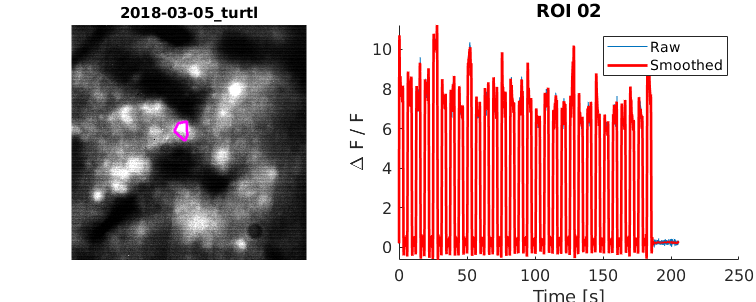

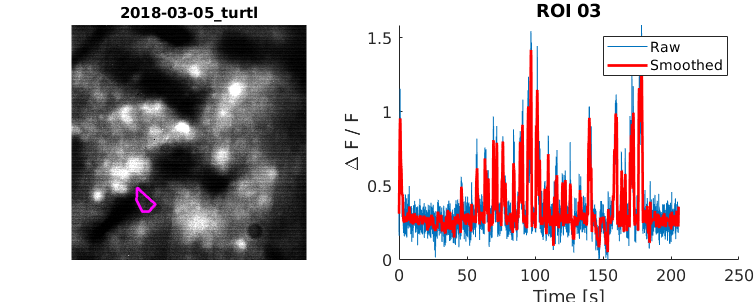

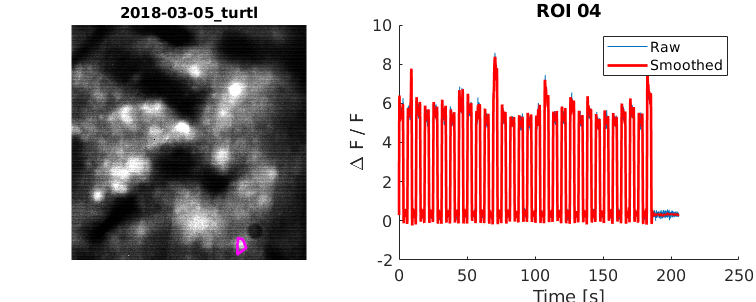

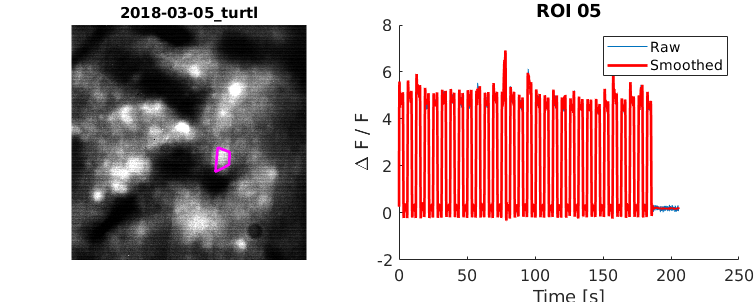

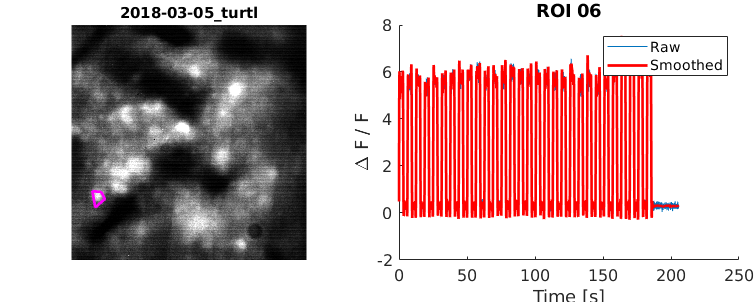

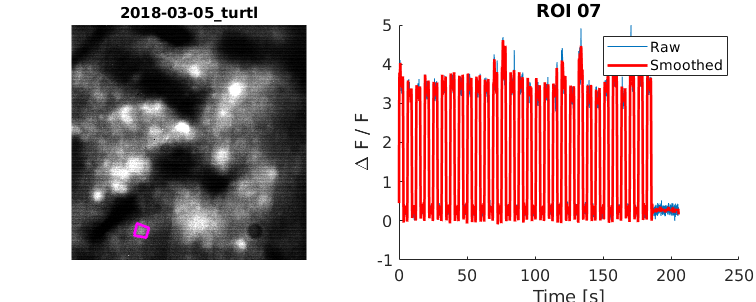

calcium_data = dir(calcium_file);    
%filtered_data = filter_hilolike_from_file_par(calcium_data.name); %if the file is raw .sif
filtered_data = calcium_data.name;
[stats,datasum]= zprofile(filtered_data,'fps',18.38); %fps should be detected automatically

##          Generating a .tif file without fluo_OFF periods to visualise followers

calcium = imread.universal();

summed = sumframe(calcium);

Undefined function or variable 'calcium'.

figure
plot(summed)

threshold = 3e6 %this should be tailored for now thanks to the visual input given by the previous figure
fluo_OFF = summed < threshold;
extracted_sweeps = calcium;
extracted_sweeps(:,:,fluo_OFF) = []; %removing all frames with no fluorescence
util.imwritetiff(extracted_sweeps,'2018-03-05_extracted_sweeps_from_m0503__c7_hilolikefiltered.tif','close',true)

summed2 = sumframe(extracted_sweeps);
figure
plot(summed2) %just checking out how the fused periods look like, id est if the threshold was good

##         If the calcium file has regions of fluo_ON and fluo_OFF

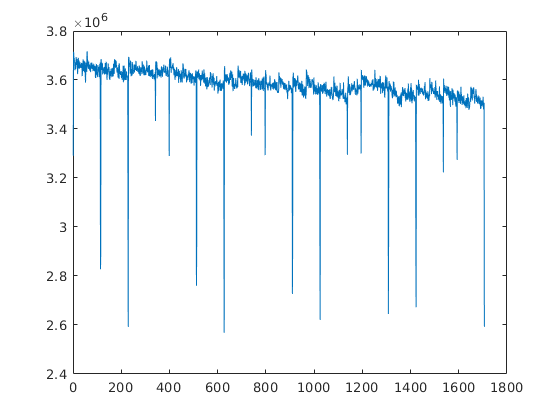

[loc_ONSET,loc_OFFSET] = fluorescence_variations(calcium_file);

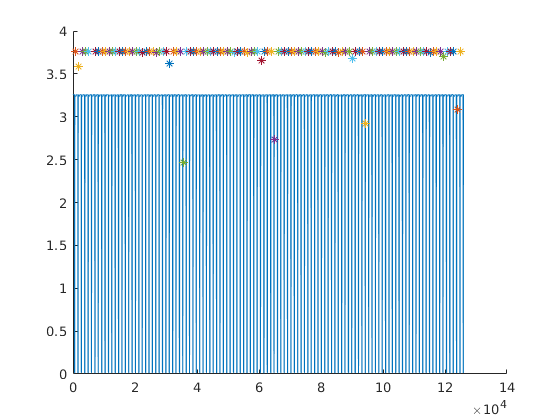

individual_fluorescence_sweeps = zeros(loc_OFFSET(1)-loc_ONSET(1)-1,length(loc_ONSET),length(stats));
%here we create a big 3D matrix with D1 = points (value in frame) minus 2 because we start at loc_ONSET +1 and stop at loc_OFFSET -1, D2 =
%sweeps, D3 = ROIs
for region=1:length(stats) %let us now fill in this matrix
    for sweep=1:length(loc_ONSET)
        c = 1;
        for value=(loc_ONSET(sweep)+1):(loc_OFFSET(sweep)-1) %we crop the region a bit to be sure
            individual_fluorescence_sweeps(c,sweep,region) = stats{region}.intensraw(value); %we are storing the value of the raw intensity
            c = c+1;
        end
    end
end

[fires, ~] = fire_detection(1,electrophysiology_data,h);

start_sweep = fires(loc_ONSET(1)+1) ;
stop_sweep = fires(loc_OFFSET(1)-1) ; %we want to plot traces (electrophy and calcium) which span the same time duration, 
%so we need to find - based on the frames - from which point to start and
%at which point to stop in the ephys trace. We still crop it a bit to be
%sure not to have weird fluorescence traces



%now we can interpolate the calcium data with the electrophy one
interpolated_calcium_data = zeros(stop_sweep-start_sweep+1,length(loc_ONSET),length(stats)); %This matrix is going to replace the individual fluorescence one. Our goal is to generate missing points between
%fire points in the electrophysiology dataset which are the only locations to which a calcium value is currently attributed. 
nb_fire_points = loc_OFFSET(1)-loc_ONSET(1)-1; %These are the current electrophysiology points for which there already exists a fluorescence value
current_fire_points = linspace(0,stop_sweep-start_sweep+1,nb_fire_points);
ultimate_resolution = linspace(0,stop_sweep-start_sweep+1,stop_sweep-start_sweep+1); %This is the list of points for which we eventually need a value

for region=1:length(stats)
    for sweep=1:length(loc_ONSET)
        interpolated_calcium_data(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps(:,sweep,region),ultimate_resolution); %Hence we interpolate
    end
end

##         If the calcium file has only fluo_ON periods - HighPulse protocole

[fires, fire_number] = fire_detection(1,electrophysiology_data,h);

individual_fluorescence_sweeps = zeros(fire_number,length(loc_ONSET),length(stats));
%here we create a big 3D matrix with D1 = points (value in frame) minus 2 because we start at loc_ONSET +1 and stop at loc_OFFSET -1, D2 =
%sweeps, D3 = ROIs
for region=1:length(stats) %let us now fill in this matrix
    for sweep=1:ephys_sweeps
        for value=1:fire_number %we crop the region a bit to be sure
            individual_fluorescence_sweeps(value,sweep,region) = stats{region}.intensraw(value); %we are storing the value of the raw intensity
        end
    end
end

start_sweep = fires(1) ;
stop_sweep = fires(end) ; %we want to plot traces (electrophy and calcium) which span the same time duration, 
%so we need to find - based on the frames - from which point to start and
%at which point to stop in the ephys trace. 

%now we can interpolate the calcium data with the electrophysiology one
interpolated_calcium_data = zeros(stop_sweep-start_sweep+1,ephys_sweeps,length(stats)); %This matrix is going to replace the individual fluorescence one. Our goal is to generate missing points between
%fire points in the electrophysiology dataset which are the only locations to which a calcium value is currently attributed. 
current_fire_points = fires(1:length(fires)); %These are the current electrophysiology points for which there already exists a fluorescence value
ultimate_resolution = linspace(0,stop_sweep-start_sweep+1,stop_sweep-start_sweep+1); %This is the list of points for which we eventually need a value

for region=1:length(stats)
    for sweep=1:ephys_sweeps
        interpolated_calcium_data(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps(:,sweep,region),ultimate_resolution); %Hence we interpolate
    end
end

Error using interp1>reshapeAndSortXandV (line 424)
X and V must be of the same length.

Error in interp1 (line 93)
    [X,V,orig_size_v] = reshapeAndSortXandV(varargin{1},varargin{2});

        And now for the 2s_protocol, we crop the signals top 0.5s before the 2s injection and 1s after

[LOC,~] = findpeaks(electrophysiology_data, 'MinPeakHeight',20);
first_spike = LOC(1,1); %corresponds to the beginning of the current injection

%now, we want to keep points up to 0.5s before the beginning and 1s after
%the end of the current injection

start_sweep = first_spike - (0.5/si)*1e6;
stop_sweep = first_spike + (3/si)*1e6; %3 and not 2 because the current injection itself spans 2s

[fires, fire_number] = fire_detection(1,electrophysiology_data,h);
%now we need to find the closest fire corresponding to these two points

start_point = 1e100;
stop_point = 1e100;
for k=1:length(fires) %we go through the list and find the minimal difference between the two points and a fire point
    diff_start = abs(fires(k)-start_sweep);
    diff_stop = abs(fires(k)-stop_sweep);
    if diff_start < start_point 
        start_point = fires(k);
        start_frame = k; %we also store the frame number
    end
    if diff_stop < stop_point
        stop_point = fires(k);
        stop_frame = k;
    end
end

start_sweep = start_point; %just for simplicity and reduce the nb of notations
stop_sweep = stop_point;

loc_ONSET = zeros(h.lActualEpisodes,1);
loc_OFFSET = zeros(h.lActualEpisodes,1);
for k=1:length(loc_ONSET)
    loc_ONSET(k) = start_frame + (k-1)*fire_number; %the next calcium sweep is actually just a shift of the window by fire_number
    loc_OFFSET(k) = stop_frame + (k-1)*fire_number;
end

individual_fluorescence_sweeps = zeros(start_frame - stop_frame,length(loc_ONSET),length(stats));
%here we create a big 3D matrix with D1 = points (value in frame) minus 2 because we start at loc_ONSET +1 and stop at loc_OFFSET -1, D2 =
%sweeps, D3 = ROIs
for region=1:length(stats) %let us now fill in this matrix
    for sweep=1:length(loc_ONSET)
        c=1;
        for value=loc_ONSET(sweep):loc_OFFSET(sweep) %we crop the region a bit to be sure
            individual_fluorescence_sweeps(c,sweep,region) = stats{region}.intensraw(value); %we are storing the value of the raw intensity
        end
    end
end

%now we can interpolate the calcium data with the electrophy one
interpolated_calcium_data = zeros(stop_sweep-start_sweep+1,length(loc_ONSET),length(stats)); %This matrix is going to replace the individual fluorescence one. Our goal is to generate missing points between
%fire points in the electrophysiology dataset which are the only locations to which a calcium value is currently attributed. 
nb_fire_points = stop_frame-start_frame+1; %These are the current electrophysiology points for which there already exists a fluorescence value
current_fire_points = linspace(0,stop_sweep-start_sweep+1,nb_fire_points);
ultimate_resolution = linspace(0,stop_sweep-start_sweep+1,stop_sweep-start_sweep+1); %This is the list of points for which we eventually need a value

for region=1:length(stats)
    for sweep=1:length(loc_ONSET)
        interpolated_calcium_data(:,sweep,region) = interp1(current_fire_points,individual_fluorescence_sweeps(:,sweep,region),ultimate_resolution); %Hence we interpolate
    end
end

##         Plotting individual ROI traces against the electrophysiology one

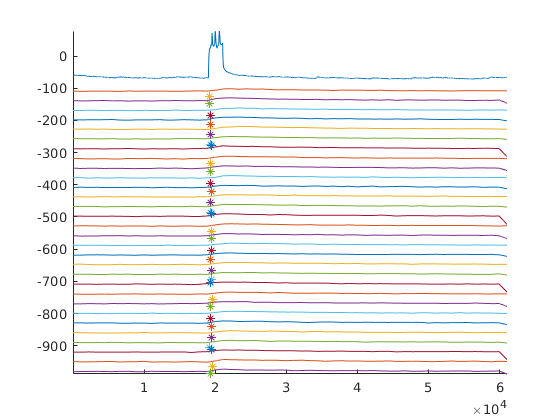

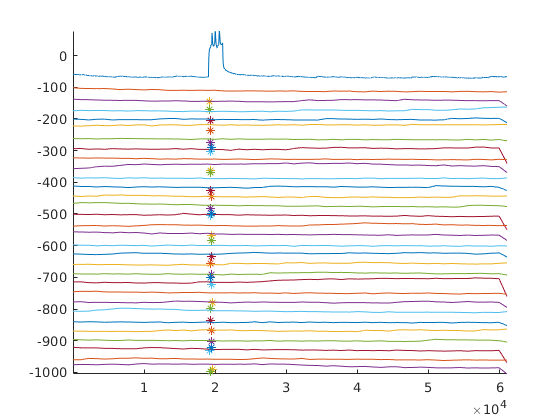

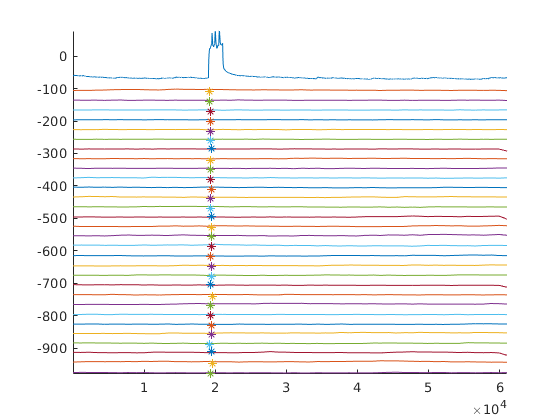

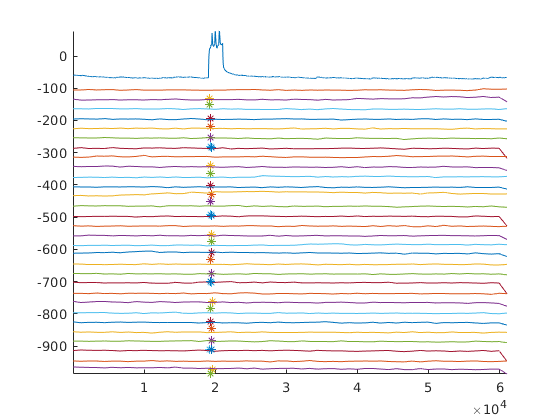

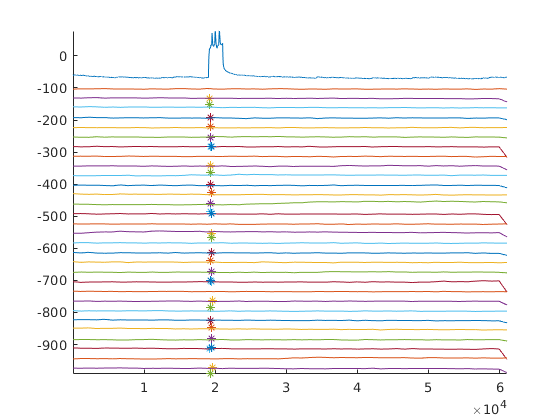

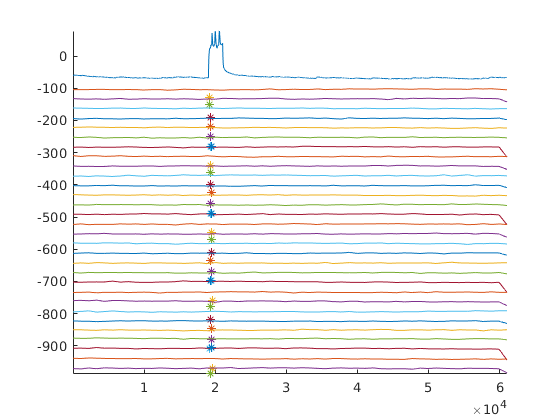

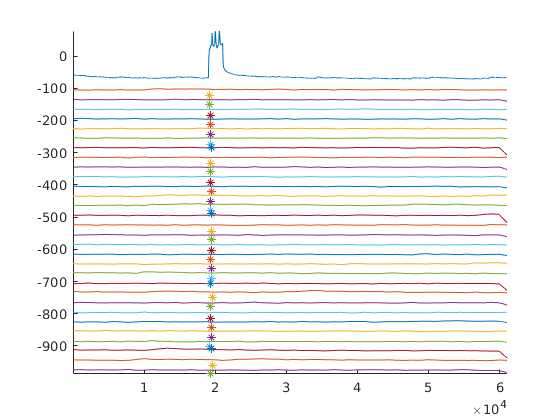

spikes = zeros(ephys_sweeps,1); %we create a list that will contain the location of the first spike for each
%sweep, it is just for plotting purposes
for k=1:ephys_sweeps
    [~,LOC]=findpeaks(electrophysiology_data(start_sweep:stop_sweep,channel,k),'MinPeakHeight',20); %finding the first peak of the k-ieth sweep
    spikes(k)= LOC(1,1); 
end


for region=1:length(stats) %first we choose a ROI
    
    y1 = min(electrophysiology_data(:,channel,1));
    y2 = max(interpolated_calcium_data(:,1,region));
    diff = y2 - y1;
    diffa = abs(diff);
    if diff == diffa
     shift = 30 + diff;
    else
     shift = 30 - diff; %with this small calculation we are able to align the y axes of both traces, then to shift the calcium one by 30 units... (*)
    end
    
    figure('Name',num2str(region)); hold on %creating a figure specifically for this region and naming it correctly
    plot(electrophysiology_data(start_sweep:stop_sweep,channel,1)) %We start by the ephys trace, sweep1: it is cropped to the fluorescence_ON period
    for n=1:length(loc_ONSET) %and then plot all fluorescence traces recorded in this ROI while light was on
        plot(interpolated_calcium_data(:,n,region)-(shift+(n-1)*30)) %...(*) and then each time we plot a new sweep, it is shifted by 30 units down again
        star_position = max(interpolated_calcium_data(:,n,region))- min(interpolated_calcium_data(:,n,region));
        plot(spikes(n),star_position - (shift+(n-1)*30), '*') %we add a start at the location of the spiking onset, it has to be shifted along the sweeps
    end
    axis tight
end

##         Plotting average ROI traces against the electrophysiology one (1 figure)

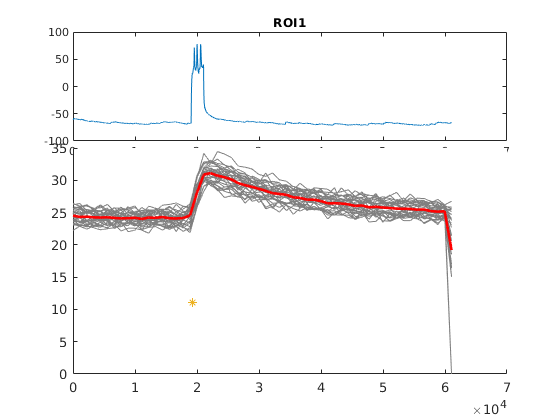

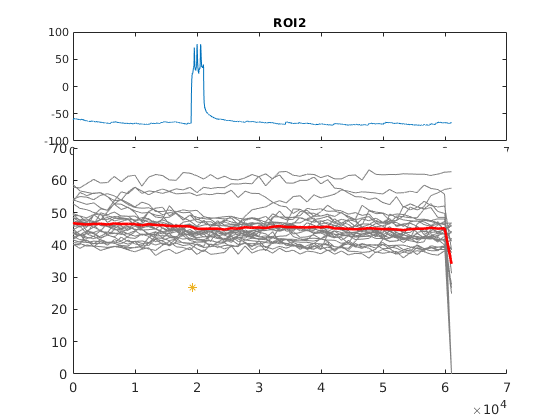

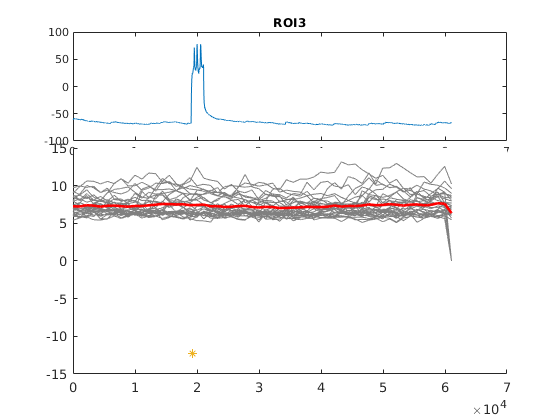

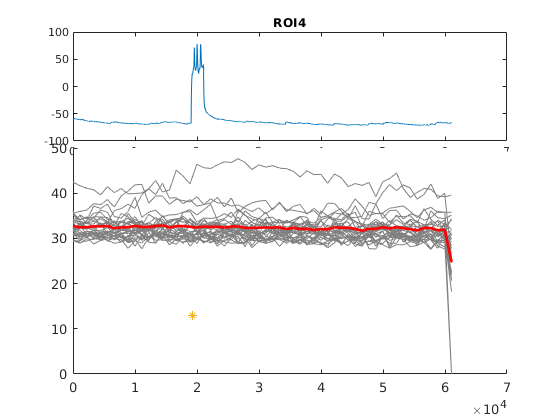

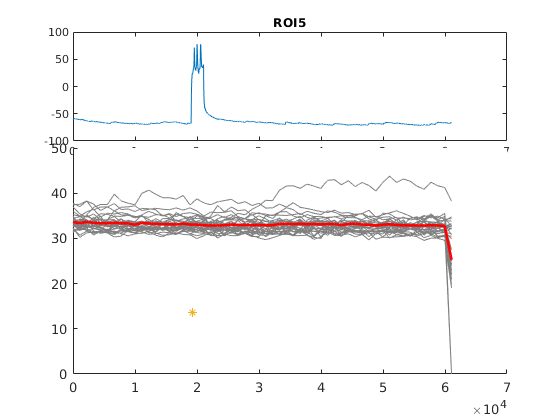

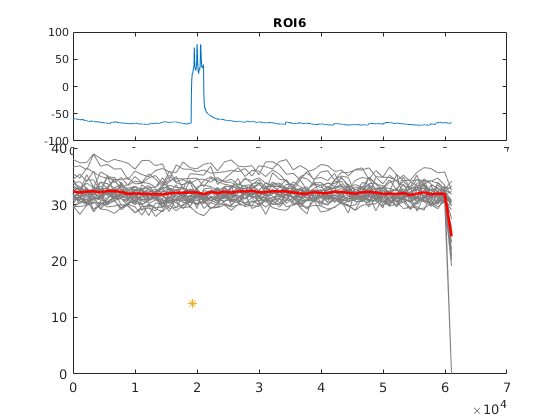

first_spike = spikes(1);


for region=1:length(stats)
    axh=[]; figure('Name','Average traces'), hold on  %This time we create one only figure for all ROIs with average traces 
    axh(1) = subplot(15,1,1:5);
    plot(squeeze(electrophysiology_data(start_sweep:stop_sweep,channel,1)))
    title(['ROI', num2str(region)])
    axh(2) = subplot(15,1,6:15); hold on
    for sweep=1:length(loc_ONSET)
        plot(interpolated_calcium_data(:,sweep,region),'Color',[.5 .5 .5])
    end
    plot(squeeze(mean(interpolated_calcium_data(:,:,region),2)),'r','Linewidth',2)
    star_position = max(mean(individual_fluorescence_sweeps(:,:,region),2))-20;
    plot(first_spike,star_position, '*')
    
end

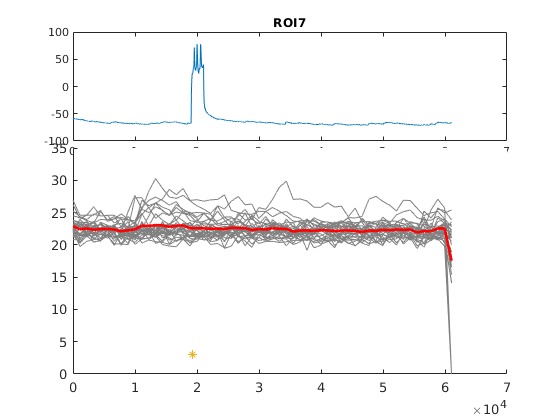

linkaxes(axh,'x')

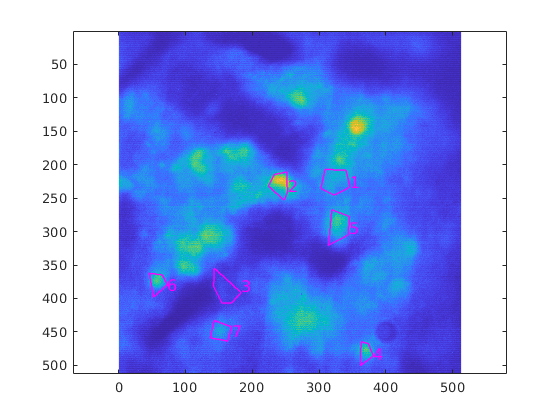

zprofile_showallrois('2018-03-05_turtle_AK15_m0503__c7_hilolikefiltered_zprofiles.mat') %we plot all ROIs 

##         Showing the average fluorescence figure with ROI colour gradient

          Pink is the colour for minimal amplitude and red for maximal amplitude

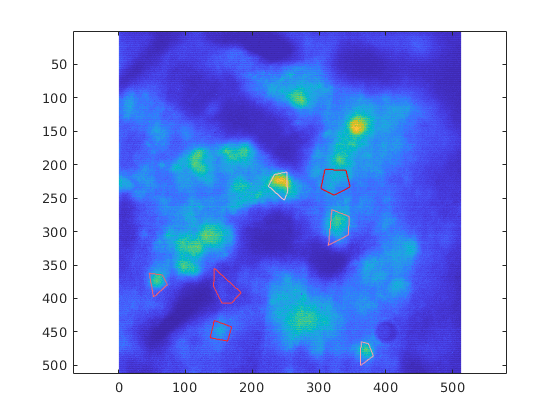

amplitude_deltaF = zeros(length(stats),1); %we want to calculate the variation amplitude of fluorescence for each ROI, we still perform this calculation on the non-interpolated values 

for region=1:length(stats)
    amplitude_deltaF(region) = max(mean(individual_fluorescence_sweeps(:,:,region))) - min(mean(individual_fluorescence_sweeps(:,:,region)));
%... so we do so using the mean, store everything in a list
end

red = [1, 0, 0]; %now here we go a bit fancy, we create a color gradient based on amplitude, defining pink (min) and red (max
pink = [255, 192, 203]/255;
colors_p = [linspace(red(1),pink(1),length(stats))', linspace(red(2),pink(2),length(stats))', linspace(red(3),pink(3),length(stats))'];

region_ranking = zeros(length(stats),1);
for region=1:length(stats)
    mini = min(amplitude_deltaF);
    mini_r = find(amplitude_deltaF==mini);
    region_ranking(region)=mini_r;
    amplitude_deltaF(mini_r)=10e6;
end

figure
imagesc(datasum)
axis equal
hold on

for region=1:length(stats)
    plot(stats{region}.boundary{1}(:,2),stats{region}.boundary{1}(:,1),'Color',colors_p(find(region_ranking==region),:))
end

##         Plotting and aligning electrophysiology sweeps w/ calcium sweeps one by one

This function has to be called within the command window for the live script will not react to it. The animated sweeps function is such that you can navigate through sweeps by using the arrow keys.

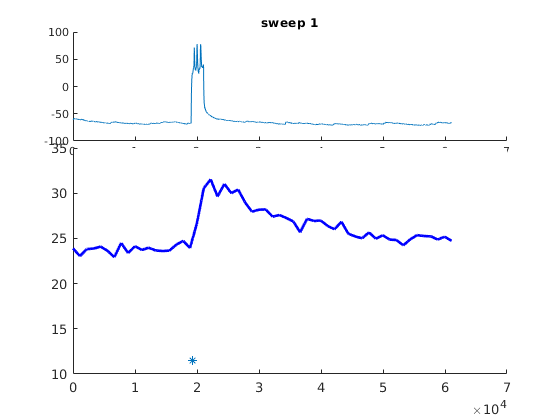

region = 1; %default, has to be set manually
animated_sweeps(electrophysiology_data,spikes,channel,start_sweep,stop_sweep,interpolated_calcium_data,region,loc_ONSET)